## Ejemplo - Prediciendo Secuencias Futuras

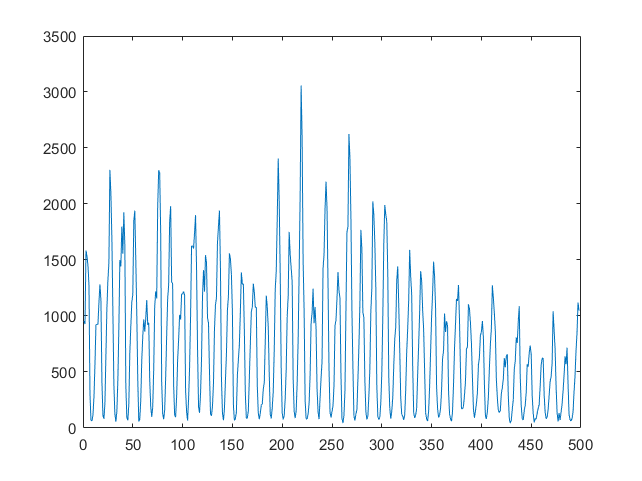

clear;
data = chickenpox_dataset;

% Se convierte los datos contenidos en celdas a un array de 1x498. Cada
% valor consiste del número de infectados en un mes diferente.
data = [data{:}];
figure; plot(data);

% El número de muestras para entrenamiento será igual a 90% de las muestras
% totales.
num_steps_train = floor(0.9 * numel(data));

% Se extrae la data de entrenamiento y de test. La de data corresponde al
% 90% y el test a la cantidad restante.
train = data(1:num_steps_train+1);
test = data(num_steps_train+1: end);

% Se estandarizan los datos de entrenamiento
mu = mean(train);
sigma = std(train);
std_train_data = (train - mu) / sigma;


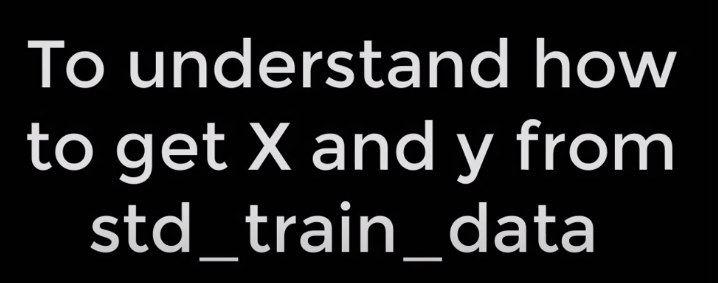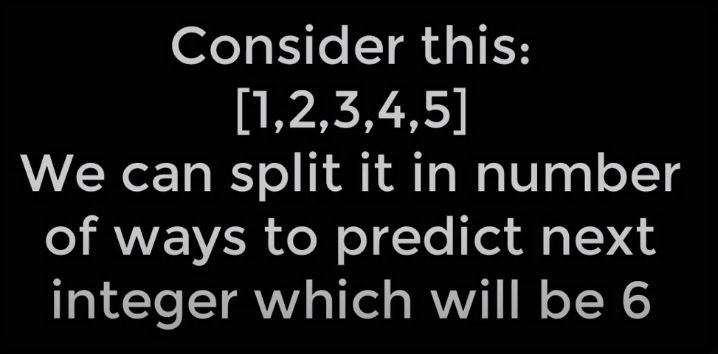

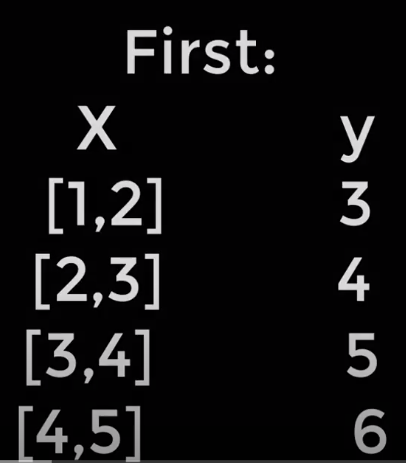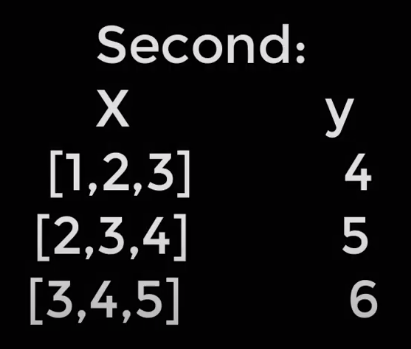

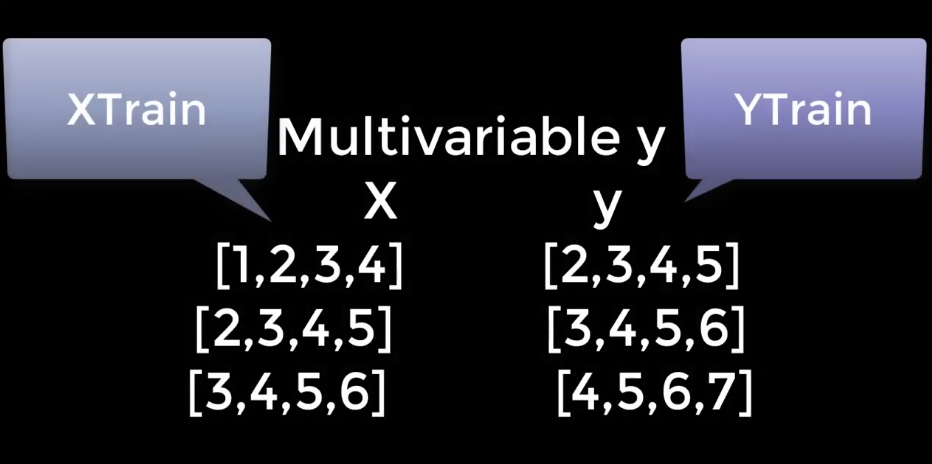

% Se emplea una forma similar al primer método, la única diferencia es que
% en lugar de que X tenga 2 columnas, este solo tiene 1. "Y" solo es un
% desfase en una iteración de "X".
XTrain = std_train_data(1:end-1)

XTrain =     0.3072    0.2589    1.3541    1.2726    1.1261    0.8331   -0.7798   -1.1710   -1.1809   -1.0911   -0.8264   -0.3437    0.2506    0.2605    0.2556    0.5818    0.8498    0.6168   -0.6000   -1.0944   -1.1477   -0.9179   -0.2089    0.4952    0.9130    1.1677    2.5526    2.2014    1.5356    0.4520   -0.6350   -1.0727   -1.1909   -1.0378   -0.5751    0.1973    1.2127    1.1161    1.7104    1.3059    1.9218    1.4374   -0.6533   -1.1343   -1.1710   -0.9346   -0.1739    0.2223    0.5868    0.7000


YTrain = std_train_data(2:end)

YTrain =     0.2589    1.3541    1.2726    1.1261    0.8331   -0.7798   -1.1710   -1.1809   -1.0911   -0.8264   -0.3437    0.2506    0.2605    0.2556    0.5818    0.8498    0.6168   -0.6000   -1.0944   -1.1477   -0.9179   -0.2089    0.4952    0.9130    1.1677    2.5526    2.2014    1.5356    0.4520   -0.6350   -1.0727   -1.1909   -1.0378   -0.5751    0.1973    1.2127    1.1161    1.7104    1.3059    1.9218    1.4374   -0.6533   -1.1343   -1.1710   -0.9346   -0.1739    0.2223    0.5868    0.7000    1.7953


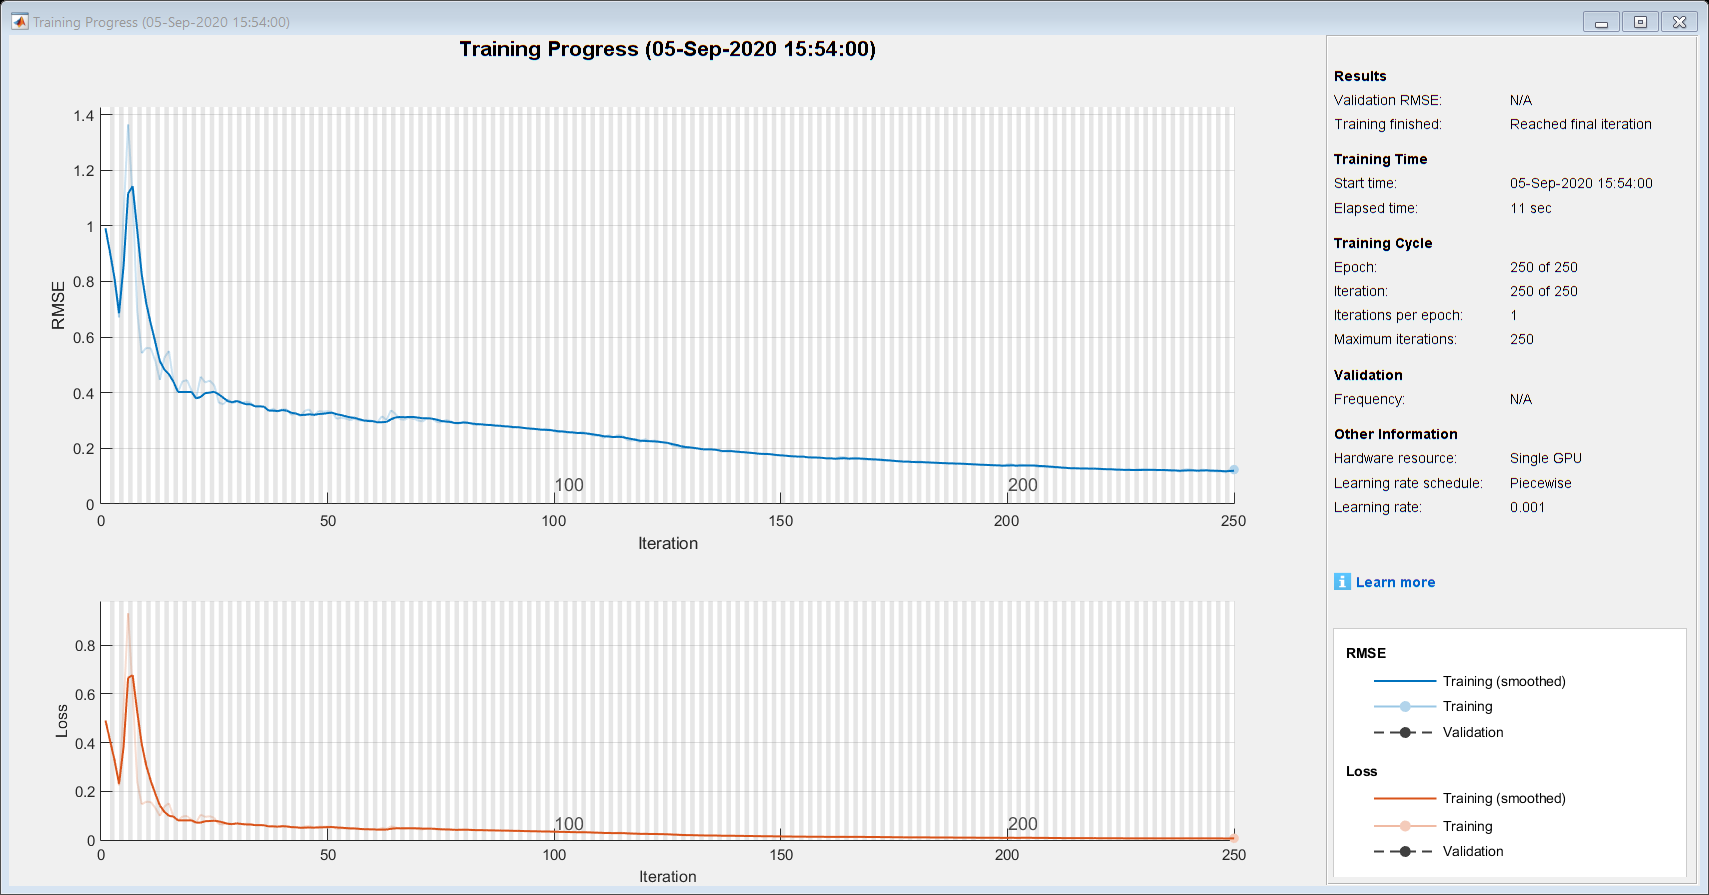

num_features = 1;               % Dimensiones de X
num_responses = 1;              % Dimensiones de Y
num_hidden_units = 200;         % Neuronas en red LSTM

layers = [sequenceInputLayer(num_features)
          lstmLayer(num_hidden_units)
          fullyConnectedLayer(num_responses)
          regressionLayer];
      
options = trainingOptions('adam','MaxEpochs',250,'GradientThreshold',1,...
                          "InitialLearnRate",0.005,'LearnRateSchedule',"piecewise",...
                          "LearnRateDropPeriod",125,'LearnRateDropFactor',0.2,'Verbose',0,...
                          'Plots',"training-progress");
                      
net = trainNetwork(XTrain,YTrain,layers,options);

% Se estandariza la data de prueba usando la media y variación estándar
std_test_data = (test-mu) / sigma;

% Para probar se toma toda la variable "std_test_data" excluyendo el último
% valor.
XTest = std_test_data(1:end-1);

% Inicializar el estado de la red primero prediciendo sobre las muestras de
% XTrain.
net = predictAndUpdateState(net,XTrain);

% Realiza la primera predicción utilizando el último "time-step" de la
% respuesta de entrenamiento "YTrain(end)"
[net,YPred] = predictAndUpdateState(net,YTrain(end));

% Usar la predicción previa como input dentro de un for loop.
% Se están prediciendo los valores de "Y" para luego compararlos con los
% valores reales que tenemos.
num_steps_test = numel(XTest);

for i=2:num_steps_test
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1));
end

% "Des-estandariza" los datos
YPred = YPred * sigma + mu;

% Datos reales para el valor de Y
YTest = test(2:end);

% Calcular el RMSE (Root mean square error)
rmse = sqrt(mean((YPred - YTest).^2))

rmse = single
222.5284

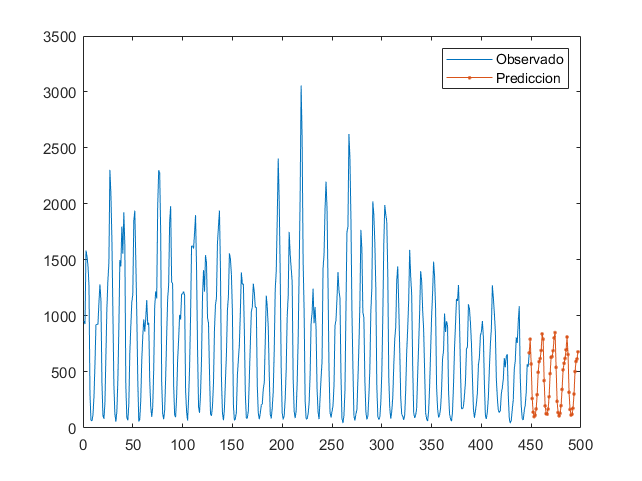


figure; 
plot(train(1:end-1));
hold on;
idx = num_steps_train:(num_steps_train + num_steps_test);
plot(idx,[data(num_steps_train) YPred],'.-');
legend(["Observado" "Prediccion"]);

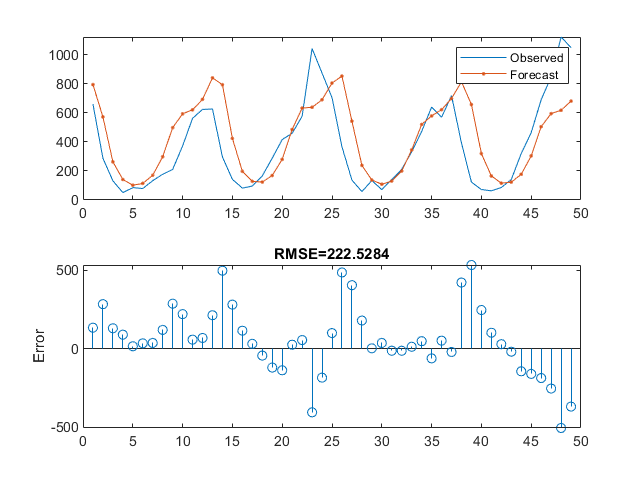


figure
subplot(2,1,1);
plot(YTest); hold on;
plot(YPred,'.-');
hold off;
legend(["Observed" "Forecast"]);
subplot(2,1,2);
stem(YPred-YTest);
ylabel("Error");
title("RMSE=" + rmse);

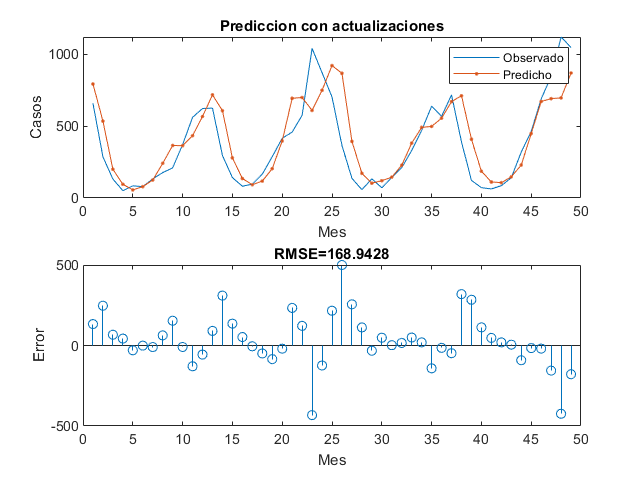

% Reinicia la red e inicializala prediciendo sobre XTrain
net = resetState(net);
net = predictAndUpdateState(net,XTrain);
YPred = [];

% Hasta este punto no se había utilizado XTest. Ahora se utilizará XTest en
% lugar de YPred en el mismo for loop como previamente vimos
for i  = 1:num_steps_test
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i));
end

YPred = sigma * YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2));

figure;
subplot(2,1,1);
plot(YTest);
hold on;
plot(YPred,'.-');
hold off;
legend(["Observado" "Predicho"]);
ylabel("Casos");  xlabel("Mes");
title("Prediccion con actualizaciones");

subplot(2,1,2);
stem(YPred-YTest);
ylabel("Error"); xlabel("Mes");
title("RMSE=" + rmse);

## Ejemplo - Modelado de Lorenz 63

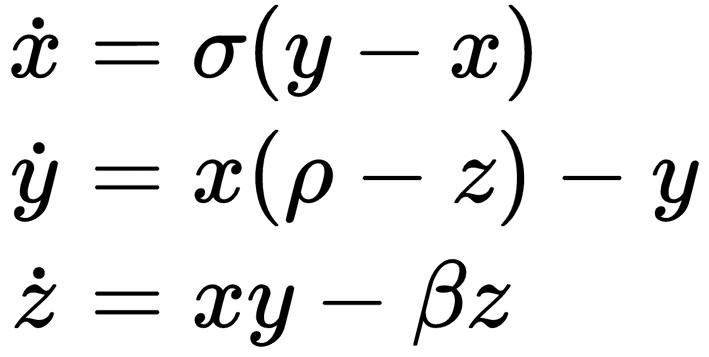

% Simulación del sistema de Lorenz
dt = 0.01; T = 8; t = 0:dt:T;
b = 8/3; sig = 10; r = 28;

% Definición de las ecuaciones de Lorenz
Lorenz = @(t,x) ([sig * (x(2) - x(1)) ; ...
                  r * x(1) - x(1) * x(3) - x(2) ; ...
                  x(1) * x(2) - b*x(3)          ]);

% Opciones del solver de ecuaciones diferenciales
ode_options = odeset('RelTol',1e-10, 'AbsTol', 1e-11);

% Vectores de entrada y salida vacíos
input = []; output = [];

% 100 trayectorias de entrenamiento
for j = 1:100
    x0 = 30*(rand(3,1) - 0.5);              % Condiciones iniciales aleatorias
    
    % "y" consiste de un vector que contiene las variables de estado (Las
    % variables que inicialmente eran iguales a x0) en su evolución a lo
    % largo del tiempo. Cada columna es una variable de estado distinta y
    % cada fila son las variables de estado en un time step diferente.
    [t,y] = ode45(Lorenz,t,x0);             
    
    input = [input ; y(1:end-1,:)];         % Append de los time steps actuales
    output = [output ; y(2:end,:)];         % Append de los time steps retrasados 1 iteración
    plot3(y(:,1),y(:,2),y(:,3)); hold on;   % Gráfica trayectorias
    plot3(x0(1),x0(2),x0(3),'ro');          % Gráfica condiciones iniciales.
end

grid on; view(-23,18)

% 3 capas intermedias. 10 neuronas por capa.
net = feedforwardnet([10 10 10]);

net.layers{1}.transferFcn = 'logsig';       % Función de activación "log sigmoide"
net.layers{2}.transferFcn = 'radbas';       % Función de activación "radial basis"
net.layers{3}.transferFcn = 'purelin';      % Función de activación "Puramente lineal"

% Se realiza la transpuesta con ".'" para hacer la transpuesta
% normal. Si solo se utiliza "'" entonces se realiza la transpuesta
% compleja conjugada. Los resultados pueden parecer similares, pero
% cambian para matrices con números imaginarios.
net = train(net,input.',output.');

figure(2);
x0 = 20*(rand(3,1)-0.5);
[t,y] = ode45(Lorenz,t,x0);
plot3(y(:,1),y(:,2),y(:,3)); hold on;
plot3(x0(1),x0(2),x0(3),'ro','LineWidth',[2]);
grid on

ynn(1,:) = x0;
for jj = 2:length(t)
   y0 = net(x0);
   ynn(jj,:) = y0.';
   x0 = y0;
end

plot3(ynn(:,1),ynn(:,2),ynn(:,3),':','LineWidth',[2]);

figure(3);
subplot(3,2,1), plot(t,y(:,1),t,ynn(:,1),'LineWidth',[2]);
subplot(3,2,3), plot(t,y(:,1),t,ynn(:,2),'LineWidth',[2]);
subplot(3,2,5), plot(t,y(:,1),t,ynn(:,3),'LineWidth',[2]);